# Generate Degradation Profiles

Reproduce this curve for an arbitrary day where the threshold is reached:

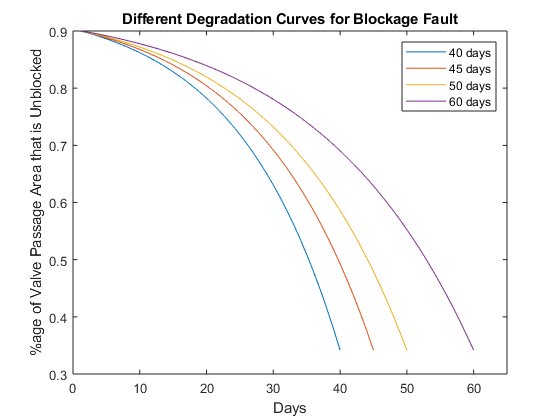

Load proxy degradation profiles.

load('sim_param_values.mat')

Select day of failure and generate degradation profile:

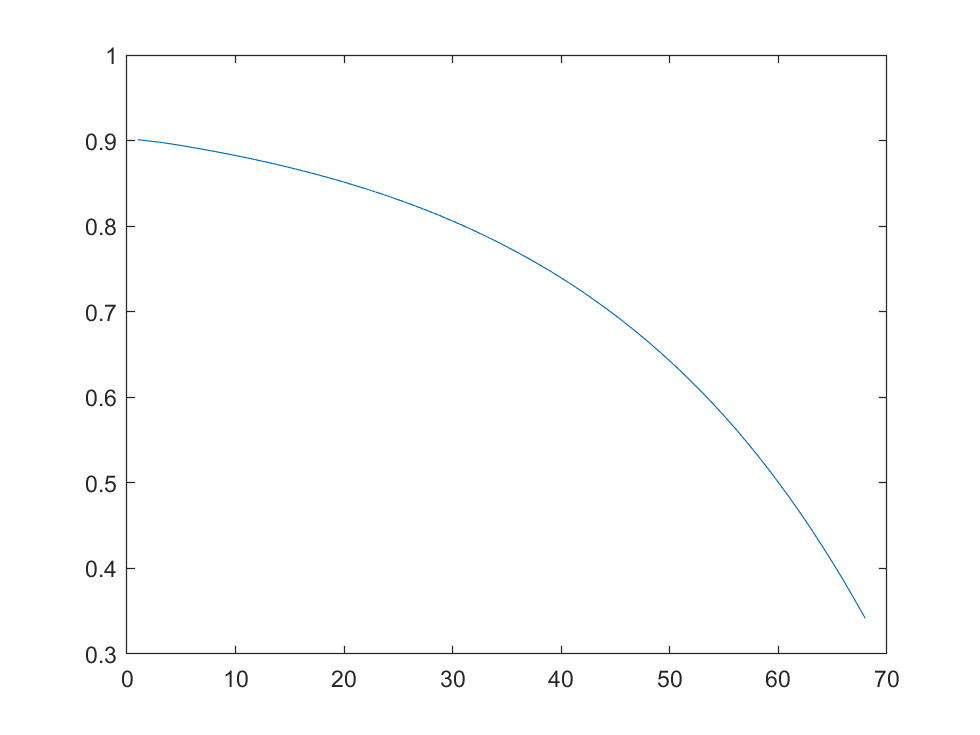

DayOfFailure = 68;

% Use "block_40" as a degradation proxy
OldTimeRange = (1:40)/40;
NewTimeRange = (1:DayOfFailure)/DayOfFailure;
block = interp1(OldTimeRange,block_40,NewTimeRange,'linear','extrap');
plot(block);

Export block to a MAT file, so that it can be loaded in "DOEGenerationScript" and used to run new simulations for RUL estimation.

save("block_" + num2str(DayOfFailure), 'block')